%addpath 'C:\Users\anonf\OneDrive\uni\phys project\matlab\iwave\development\matlab'

f_sampling = 250e6; % Hz
t_step = 1/f_sampling;

chunk_length = 2^20;
num_samples = chunk_length * 4;

t_end = t_step * (num_samples - 1) % secs

t_end = 0.0168

t = 0 : t_step : t_end;

%% constants
c = 3e8; % m/s
h_eV = 4.136e-15; % eV
k_B = 1.38065e-23; % m2 kg s-2 K-1
h = 6.62607015e-34; % m2 kg / s
hbar_times_c = 2e-7; % eV m

%% parameters
axion_rest_energy = 2e-6; % eV/c2
axion_velocity = 240e3; % m/s
T = 10e-3; % K
axion_power = 1.5e-21; % W, from eq 2.28 of Daw thesis

% noise powers 1e-16 2e-16

%% axion signal params
f_a_original = axion_rest_energy / h_eV % Hz, default axion

f_a_original = 4.8356e+08

axion_linewidth = f_a_original * 1e-6

axion_linewidth = 483.5590

axion_Q = f_a_original / axion_linewidth

axion_Q = 1000000


f_a = f_a_original / 20 % heterodyne

f_a = 2.4178e+07


de_broglie_wavelength = 2*pi * hbar_times_c / (axion_rest_energy * axion_velocity/c);
t_coherence = de_broglie_wavelength / axion_velocity;

%% generate axion frequency
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);

%plot(t, f_axion)
%yline([f_a - axion_linewidth/2, f_a + axion_linewidth/2])

%% generate signal and noise
signal = generate_axion_signal(t, f_sampling, f_axion, axion_power);
noise_power = calculate_noise_power(f_sampling, T);
noise = generate_thermal_noise(t, f_sampling, noise_power);

x = signal + noise;
%x = noise;
%x = signal;

f_0 = f_a - 3e3

f_0 = 2.4175e+07

Q = 1e5;
y = resonator(x, f_0, f_0*ones(size(x)), Q, f_sampling);

y_chunked = reshape(y, [], chunk_length);

s = size(y_chunked);
pws = zeros(s(1), s(2)/2);

%for i = 1 : size(y_chunked, 1)
for i = 1 : size(y_chunked, 1)
    [f, pwr] = do_fft(y_chunked(i,:), f_sampling);
    pws(i,:) = pwr;
end

bin_widths = f / length(x);
bin_width = f(2) - f(1)

bin_width = 238.4186

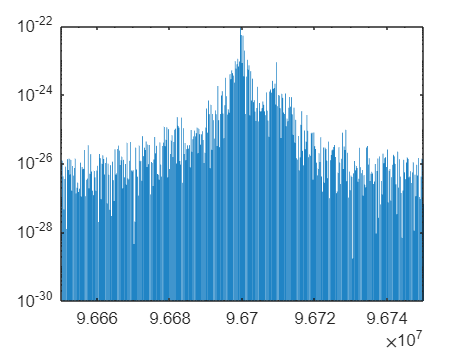


disp_width = 1e5;
start_index = find(f > 9.665e7, 1);
end_index = find(f > 9.675e7, 1);
%end_index = length(f)-1;
%start_index = find(f > f_0 - disp_width, 1);
%end_index = find(f > f_0 + disp_width, 1);
chop = start_index : end_index;

powers = mean(pws, 1);

f_ = f(chop);
p_ = powers(chop);

figure
%bar(f, pwr)
bar(f_, p_)
set(gca, 'xscale','log', 'yscale','log')

%xline(f_0)
%xline(f_a)
%xline(f_0 * 2 * pi)

omega_0 = 2*pi * f_0;
Delta_0 = omega_0 / f_sampling;
w = Delta_0 / (2 * Q);

Delta = 2*pi*f_/f_sampling;

A_Delta = (1 - exp(-w)) ./ sqrt(1 - 2*exp(-w)*cos(Delta - Delta_0) + exp(-2*w)); % from Ed paper

function [f, pwr] = do_fft(x, f_sampling)
    Y = fft(x);
    % The execution time for fft depends on the length of the transform. Transform lengths that have only small prime factors are significantly faster than those that are prime or have large prime factors.
    %Y = Y(1:end-1); % so has even number of samples
    
    L = length(Y);
    
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);

    f = f_sampling*(0:(L/2))/L;
    %f = f/ (2*pi);

    amp = P1;
    pwr = amp.^2;
    pwr = pwr(2:end);
    f = f(2:end);
end